# Radiation Shielding Lab

*Steven Henderson*

***Introduction***

In this lab I measured the reactivity of certain sources of radiation focusing on alpha, beta, and gamma radiation.

***Equations***

To measure the effectiveness of radiaiton shielding of multiple materials (Al, Pb, and air) I need a way to relate the attenuation length $\alpha$ to the number of particles detected with the geiger counter. To do this, I took this equation which relates the two,


$$\frac{\textrm{dN}}{\textrm{dx}}=-\frac{N}{\alpha }$$


and linearized it as such,


$$\int \frac{\textrm{dN}}{N}=-\frac{1}{\alpha }\int \textrm{dx}=\textrm{lnN}=-\frac{\alpha }{x}+C$$


where x is the thickness of the material used and N was the number of radiation particles detected. The log of N was then plotted against x to find the slope which should be equal to,


$$m=-\frac{1}{\alpha }$$


where m is the slope. To get measured attentuation length then,


$$\alpha =-\frac{1}{\textrm{slope}}$$


Background radiation data has also been measured and will be averaged out and removed from the data sets.

**Data Parsing**

% Parse data from spreadsheet used to collect the data
gamma_data = readmatrix('RADIATION SHIELDING.xlsx', 'Range', 'G10:Z29') ; % Gamma radiation
beta_data = readmatrix('RADIATION SHIELDING.xlsx', 'Range', 'G32:Z51') ; % Beta radiation
alpha_data = readmatrix('RADIATION SHIELDING.xlsx', 'Range', 'G54:Z73') ; % Alpha radiation
background_data = readmatrix('RADIATION SHIELDING.xlsx', 'Range', 'G76:T95') ; % Background radiation
% Parse data from matrices
% Initialize arrays
gamma_x = [] ; % Thickness of material used for gamma radiation (cm)
gamma_x_uncer = [0.05, 0.05, 0.05, 0.05] ;
gamma_N = {} ; % Number of radiation particles detected for gamma radiation 
gamma_N_sum = [] ; % Sums of counts for each trial for gamma radiation
gamma_N_err = [] ; % Error of those sums for gamma radiation 
beta_x = [] ; % Thickness of material used for beta radiation (cm)
beta_x_uncer = [0.05, 0.05, 0.05, 0.05] ;
beta_N = {} ; % Number of radiation particles detected for beta radiation 
beta_N_sum = [] ; % Sums of counts for each trial for beta radiation 
beta_N_err = [] ;  % Error of those sums for beta radiation 
alpha_x = [] ; % Thickness of material used for alpha radiation (cm)
alpha_x_uncer = [0.05, 0.05, 0.05, 0.05] ;
alpha_N = {} ; % Number of radiation particles detected for alpha radiation 
alpha_N_sum = [] ; % Sums of counts for each trial for alpha radiation
alpha_N_err = [] ;  % Error of those sums for alpha radiation 
background_sum = [] ; % Sums of the number of radiation particles detected in the backgound
background_sum_err = [] ;
% Sum up counts of radiation particles detected in the background data
for i = 2:2:14
    background_sum(end+1) = sum(background_data(:, i)) ;
    background_sum_err(end+1) = sqrt(sum(background_data(:, i))) ;
end
% Average the sums to get a consistent background 
background = mean(background_sum) ;
background_err = mean(background_sum_err) ;
% Add data to pre-initalized arrays including counts, thicknesses, sums,
% and their uncertainities
for i = 2:4:14
    gamma_N{end+1} = gamma_data(:, i) ;
    gamma_x(end+1) = gamma_data(1, i+2) ;
    gamma_N_sum(end+1) = sum(gamma_data(:, i)) ;
    gamma_N_err(end+1) = sqrt(sum(gamma_data(:, i))) ;
    beta_N{end+1} = beta_data(:, i) ;
    beta_x(end+1) = beta_data(1, i+2) ;
    beta_N_sum(end+1) = sum(beta_data(:, i)) ;
    beta_N_err(end+1) = sqrt(sum(beta_data(:, i))) ;
    alpha_N{end+1} = alpha_data(:, i) ;
    alpha_x(end+1) = alpha_data(1, i+2) ; 
    alpha_N_sum(end+1) = sum(alpha_data(:, i)) ;
    alpha_N_err(end+1) = sqrt(sum(alpha_data(:, i))) ;
end
% Remove the background radiation from the sums of radiations and propogate
% error
gamma_N_sum = gamma_N_sum - background ;
gamma_N_err = sqrt(background_err^2 + gamma_N_err.^2) ;
beta_N_sum = beta_N_sum - background ;
beta_N_err = sqrt(background_err^2 + beta_N_err.^2) ;
alpha_N_sum = alpha_N_sum - background ;
alpha_N_err = sqrt(background_err^2 + alpha_N_err.^2) ;
gamma_lnN = log(gamma_N_sum) ;
gamma_lnN_err = (1./gamma_N_sum).*gamma_N_err ;
beta_lnN = log(beta_N_sum) ;
beta_lnN_err = (1./beta_N_sum).*beta_N_err ;

**Finding Attentuation Lengths for Gamma and Beta Radiation**

In this section I found the fit lines by plotting $\textrm{lnN}\;\textrm{vs}\ldotp x$ and used the slope of that line to find $-\frac{1}{\alpha }$ and converted to just $\alpha$. These values are then compared to the ones that were predicted. For gamma with lead shielding I had,


$$\begin{array}{l}
1\ldotp 029\;\textrm{cm}\;\textrm{for}\;778\ldotp 9045\;\textrm{KeV}\;\textrm{radiation}\\
0\ldotp 283\;\textrm{cm}\;\textrm{for}\;344\ldotp 2785\;\textrm{KeV}\;\textrm{radiation}
\end{array}$$


And for beta with aluminum shielding I had,


$$0\ldotp 30\;\textrm{cm}\;\textrm{for}\;244\ldotp 05\;\textrm{KeV}\;\textrm{radiation}$$


The values expected really matter on what the percentage of radiation is at each energy level. Beta radiation is easy as I used Tl-204 which only really radiates one energy level. For gamma I used Eu-152 which radiates a lot more energy levels but only two are applicable as the attentuation lengths for the other energy levels is way too small to measure.

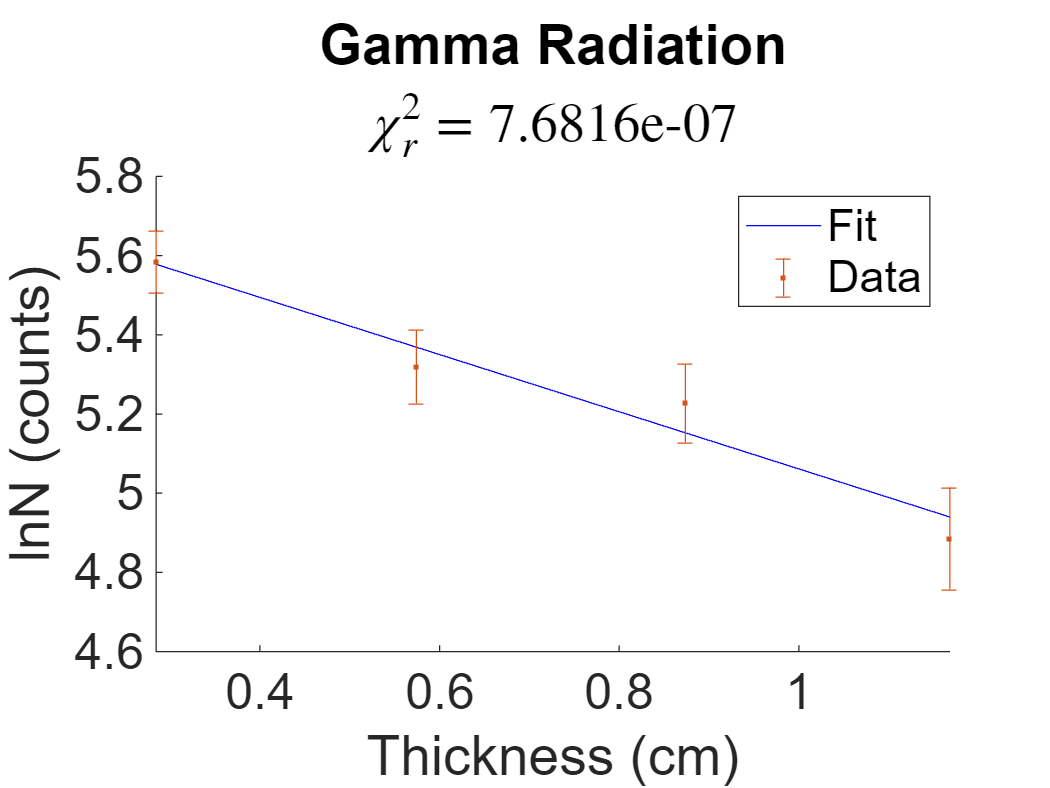

% Find fits of thickness v. log of the number of radiation particles
% detected for each type of radiation
gamma_f = wlsfit(gamma_x, gamma_lnN, gamma_lnN_err) ;
beta_f = wlsfit(beta_x, beta_lnN, beta_lnN_err) ;
gamma_fit = gamma_f(1) + gamma_f(2)*(gamma_x) ; % Fit equation to plot for gamma radiation
beta_fit = beta_f(1) + beta_f(2)*(beta_x) ; % Fit equation to plot for beta radiation
gamma_chi = findChi(gamma_x, gamma_lnN, (1./gamma_lnN_err.^2), gamma_f(2), gamma_f(1)) ; % Chi values for gamma fit
beta_chi = findChi(beta_x, beta_lnN, (1./beta_lnN_err.^2), beta_f(2), beta_f(1)) ; % Chi values for beta fit
% Plot fits and raw data
clf
hold on 
plot(gamma_x, gamma_fit, 'b')
errorbar(gamma_x, gamma_lnN, gamma_lnN_err, 'LineStyle','none', 'Marker','.')
hold off
xlabel('Thickness (cm)')
ylabel('lnN (counts)')
set(gca, 'fontsize', 20)
legend('Fit', 'Data')
subtitle(['$\chi_r^2=$', num2str(gamma_chi(2))], 'Interpreter', 'latex')
title('Gamma Radiation')

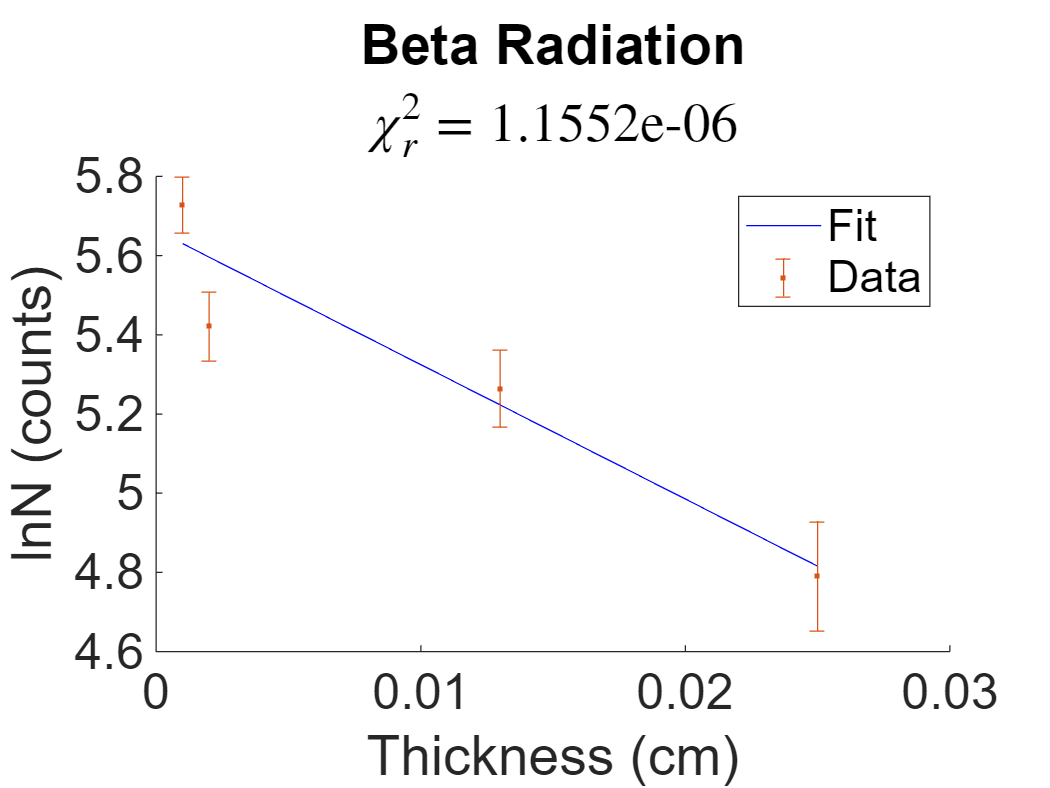

clf
hold on
plot(beta_x, beta_fit, 'b')
errorbar(beta_x, beta_lnN, beta_lnN_err, 'LineStyle','none', 'Marker','.')
xlim([0, 0.03])
hold off
xlabel('Thickness (cm)')
ylabel('lnN (counts)')
set(gca, 'fontsize', 20)
legend('Fit', 'Data')
subtitle(['$\chi_r^2=$', num2str(beta_chi(2))], 'Interpreter', 'latex')
title('Beta Radiation')

% Find measured attenutation lengths
alpha_beta = -1/(beta_f(2))

alpha_beta = 0.0295

alpha_beta_err = beta_f(4)/beta_f(2)^2

alpha_beta_err = 0.0049

alpha_gamma = -1/(gamma_f(2))

alpha_gamma = 1.3856

alpha_gamma_err = gamma_f(4)/gamma_f(2)^2

alpha_gamma_err = 0.2905

For gamma radiation and lead shielding I measured an attenuation length of,


$$\alpha =0\ldotp 0295\pm 0\ldotp 005\textrm{cm}$$


which is 0.24 $\sigma$ away from our predicted value for 344.2785 KeV radiation which means that is most likely also the most common radiation I detected.

For Beta radiation and aluminum shielding I measured,


$$\alpha =1\ldotp 39\pm 0\ldotp 30\textrm{cm}\;$$


which is $3\ldotp 63\sigma$ away from my predicted value of $0\ldotp 3\textrm{cm}$.

Possible extra uncertainities in the measurements taken could include extra background radiation from the lab as there are lots of sources of radiation that turn off and on in the lab that these meausurements were taken. Another source could be from an inaccurate measurement of distance between the sample and the gieger counter as I was changing the shelding something may have shifted.

**Find Attentuation Length for Alpha **

Finding the attentuation length for alpha radiation is a bit different as it is the hardest to measure. If I were to use aluminum or lead then the attenuation length would be so small I couldn't measure it. So, for find the attentuation length of alpha radiation I will take a measurement at x=0 and find where it falls to 1/e of its original value and take that as the attenuation length. After, I will compare with the expected value of,


$$3\ldotp 75\textrm{cm}\;\textrm{for}\;5304\ldotp 33\;\textrm{KeV}$$


% Find zero (max reading of tests)
zero = max(alpha_N_sum) ; % Sum at zero
% Find where it falls of to 1/e of itself
fall_off_sum = zero*(1/exp(1))

fall_off_sum = 694.7140

% View sums to find the closest
alpha_N_sum

alpha_N_sum = 1.0e+03 *

    0.5324    1.8884    1.0184    0.3504


% It shows that the 1st index and the 3rd are the closes so interpolate
% weighting index 1 higher
alpha_x(1)*(0.8)+alpha_x(3)*(0.2) / 2

ans = 1.1200

% All x measurements have error of 0.05 as measured with ruler

I found a value of $\alpha_{\alpha } =1\ldotp 12\pm 0\ldotp 05\textrm{cm}$ which is 52.6 $\sigma$ away from the predicted value. This is expected as alpha radiation is very hard to measure and each measurement was changing the solid angle created meaning that each measurement is not equal in volume surveyed.

% Function for calculating linear fit by weighted least squares
function fit = wlsfit(xdata,ydata,ydataerr)
% linfit: inputs are xdata, ydata, and ydata errors
% ouputs are the slope, offset, slope error and offset error
weights = 1./(ydataerr.^2) ; % find weights from errors
sumw = sum(weights) ; % sum w_i
sumwx = sum(weights.*xdata) ; % sum w_i*x_i
sumwx2 = sum(weights.*(xdata.^2)) ; % sum w_i*(x_i^2)
sumwxy = sum(weights.*xdata.*ydata) ; % sum w_i*x_i*y_i
sumwy = sum(weights.*ydata) ; % sum w_i*y_i
delta = sumw.*sumwx2 - sumwx.^2 ; %
slope = (1./delta).*( sumw.*sumwxy - sumwx.*sumwy); % Best fit slope
offset = (1./delta).* ( sumwx2.*sumwy - sumwx.*sumwxy); % Best fit intercept
sloerr = sqrt(sumw./delta); % Error on slope
offerr = sqrt(sumwx2./delta); % Error on intercept
fit = [offset, slope, offerr, sloerr] ;
end
% Function for finding chi-square and reduced chi-square with poly1 as the
% fit
function chi = findChi(xdata, ydata, ydataerr, slope, offset)
% chisq inputs: xdata, ydata, ydata errors, best fit slope and offset
% outpus: chi2 and reduced chi2
weights = 1./(ydataerr.^2) ; % find weights from errors
myfit = slope.*xdata + offset; % find best linear fit
chi2 = sum(((ydata-myfit).^2).*weights) ;
n = size(xdata,2) ; % # of data elements
rchi2 = chi2/(n-2) ; % # of degrees of freedom
chi = [chi2, rchi2] ;
end